# Laborator 3

## Problema 1

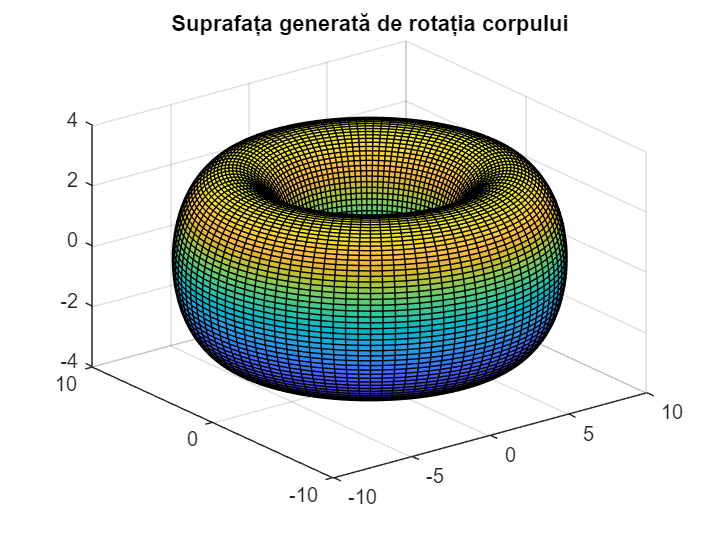

theta= linspace(0,2*pi,100);
phi= linspace(0,2*pi,100);

[theta,phi]= meshgrid(theta,phi);

x=(7+3.*cos(theta)).*cos(phi);
y=(7+3.*cos(theta)).*sin(phi);
z=3.*sin(theta);

surf(x,y,z)
title('Suprafața generată de rotația corpului')

## Problema 2

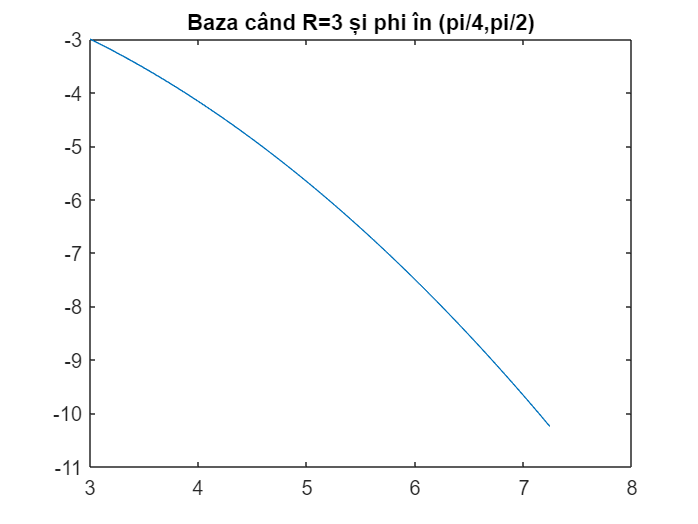

syms phi R 

x0(phi,R)=R.*cot(phi/2);
y0(phi,R)=0;

x1=x0(phi,R)-diff(y0(phi,R),phi);
y1=y0(phi,R)+diff(x0(phi,R),phi);

x=diff(x0(phi,R),phi).*sin(phi)-diff(y0(phi,R),phi).*cos(phi);
y=diff(x0(phi,R),phi).*cos(phi)+diff(y0(phi,R),phi).*sin(phi);

R1=3;
phi1=linspace(pi/4,pi/2);
R2=5;
phi2=linspace(pi/9,pi/3);

X1=matlabFunction(x1);
Y1=matlabFunction(y1);
X=matlabFunction(x);
Y=matlabFunction(y);

plot(X1(R1,phi1),Y1(R1,phi1))
title("Baza când R=3 și phi în (pi/4,pi/2)");

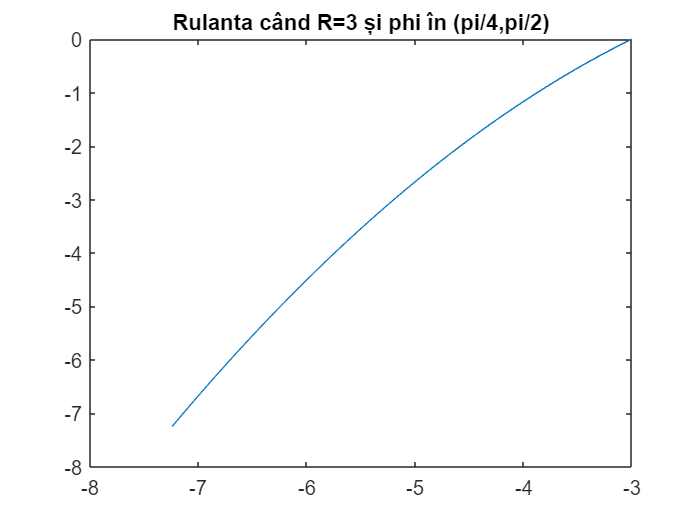


plot(X(R1,phi1),Y(R1,phi1))
title("Rulanta când R=3 și phi în (pi/4,pi/2)");

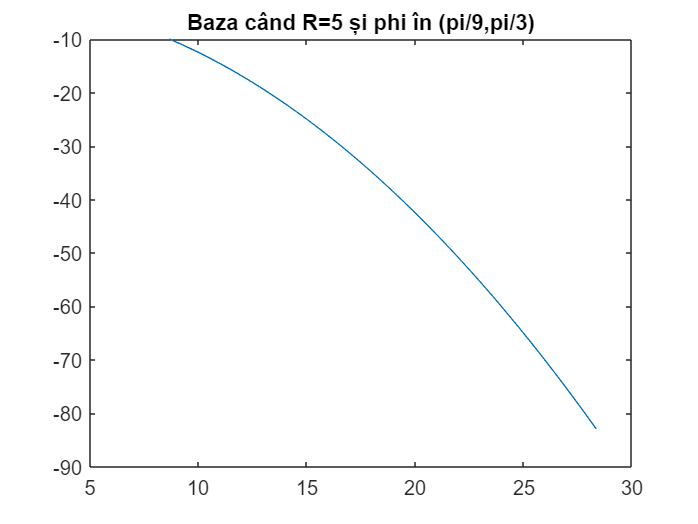


plot(X1(R2,phi2),Y1(R2,phi2))
title("Baza când R=5 și phi în (pi/9,pi/3)");

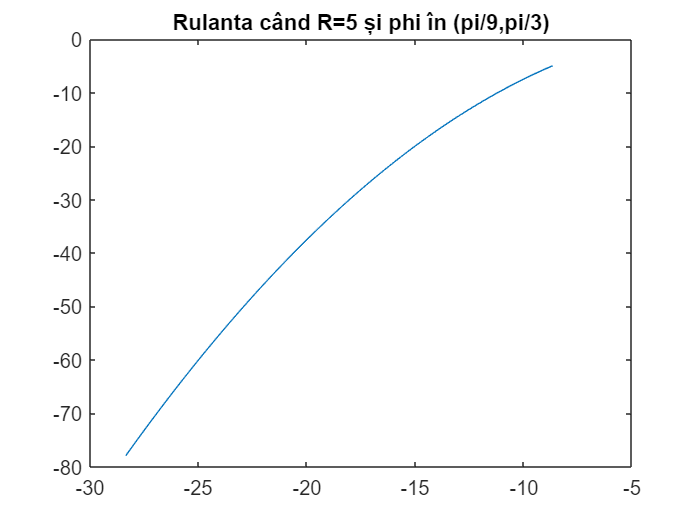


plot(X(R2,phi2),Y(R2,phi2))
title("Rulanta când R=5 și phi în (pi/9,pi/3)");